# Laboratorium 7

## Dyskretna transformacja Fouriera

Janusz Pawlicki

## 1. Ćwiczenia

### 1.1 Zadanie 1

Przeprowadź analizę sygnału x1(t) = sin(2*pi*f1*t) próbkowanego z częstotliwościę fp. Szkic programu znajduje się na rysunku 1. Analizę zacznij od 

N = 10 próbek sygnału wejściowego. Uzupełnij niekompletną implementację transformacji DFT zgodnie ze wzorem:

clear all;
close all

syms t w

N = 10; % liczba próbek
fp = 1000; % Hz
Tp = 1/fp;
A1 = 1; f1 = 100; % Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);

for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k + 1) + xn(n + 1)*(exp(-1j*2*pi/N)^(k*n));
    end
end

Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 1.8374e-14

disp('DFT error:'); disp(dft_err);

DFT error:
   1.8374e-14



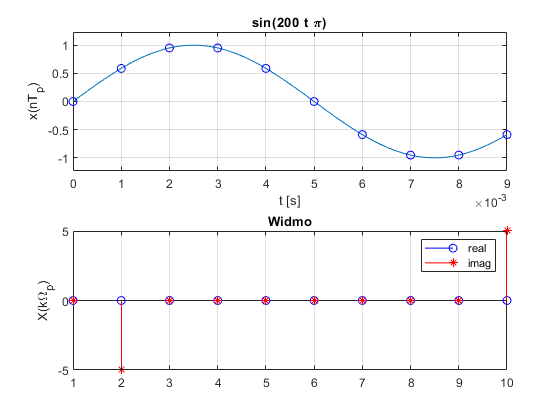


figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(2,1,2)
stem(real(Xk),'ob'); grid on, hold on
stem(imag(Xk),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')
hold off

### 1.2 Zadanie 2

Otrzymany wykres widma nie jest zupełnie poprawny. Uzgodnij skalę częstotliwości (oś x wykresu) aby była oznaczona w jednostkach częstotliwości [Hz].

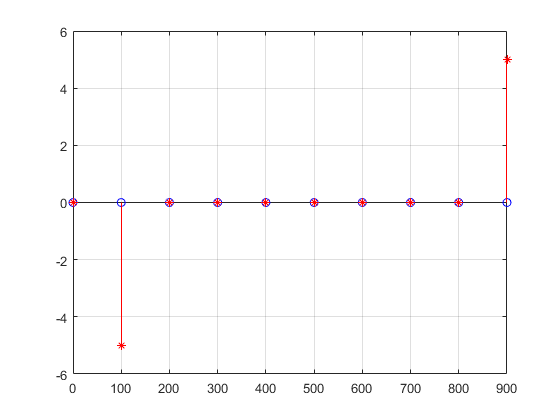

figure
wk = fp*[0:N-1]/N;    % oś częstotliwości
stem(wk, real(Xk), 'ob'); grid on; hold on;
stem(wk, imag(Xk), '*r');
hold off

### 1.3 Zadanie 3

Usuń z wykresu, tą część widma która odpowiada częstotliwościom ujemnym

(por. Podstawowe własności transformaty DFT - Symetria) pozostawiając jedynie uźyteczną część.

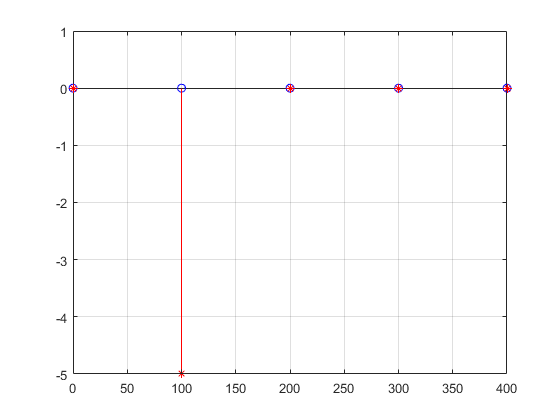

figure
wk = fp*[0:N/2-1]/N;    % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');
hold off

### 1.4 Zadanie 4

Dodaj do wykresu widmową gęstość ampiltudowy oraz widmową gęstość fazy sygnału.

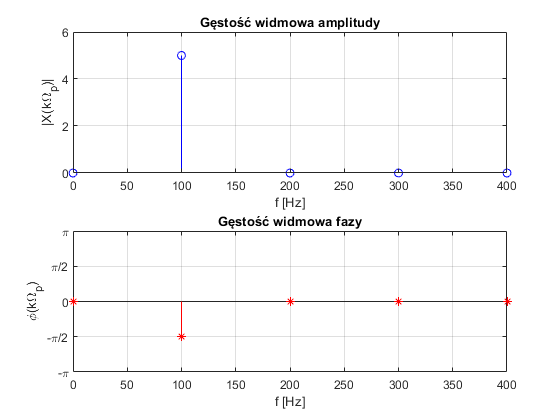

tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;

figure;
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
 
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'})
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');
hold off

### 1.5 Zadanie 5

Wyznacz widmo dla N = 15 oraz N = 20.

### N = 15

clear all;
close all

syms t w

N = 15; % liczba próbek
fp = 1000; % Hz
Tp = 1/fp;
A0 = 5;
A1 = 1; f1 = 100; % Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

tn = [0:N-1]*Tp; % wsp. czasowe próbek

xn = double(subs(x,t,tn));
Xk = zeros(1,N);

for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k + 1) + xn(n + 1)*(exp(-1j*2*pi/N)^(k*n));
    end
end

Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 1.0642e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   1.0642e-13



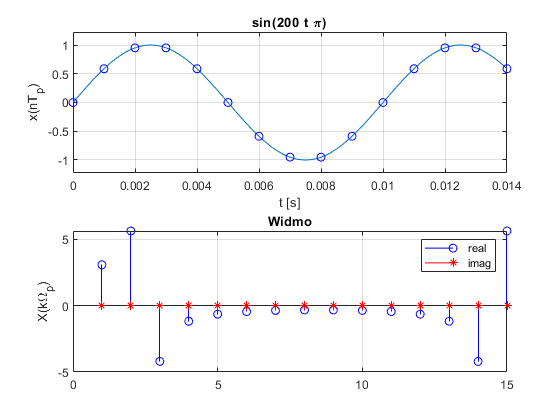


wk = fp*[0:floor(N/2)-1]/N;    % oś częstotliwości

figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(2,1,2)
stem(real(Xk),'ob'); grid on, hold on
stem(imag(Xk),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')
hold off

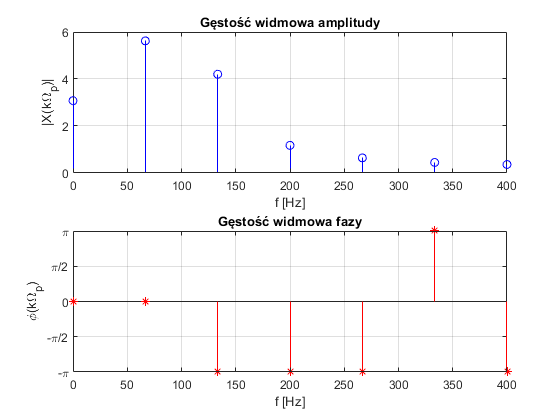


tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;

figure;
subplot(2,1,1);
stem(wk, abs(Xk(1:floor(N/2))), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
 
subplot(2,1,2);
stem(wk, angle(Xk(1:floor(N/2))), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'})
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');
hold off

### N = 20

clear all;
close all

syms t w

N = 20; % liczba próbek
fp = 1000; % Hz
Tp = 1/fp;
A0 = 5;
A1 = 1; f1 = 100; % Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);

for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k + 1) + xn(n + 1)*(exp(-1j*2*pi/N)^(k*n));
    end
end

Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 2.7865e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   2.7865e-13



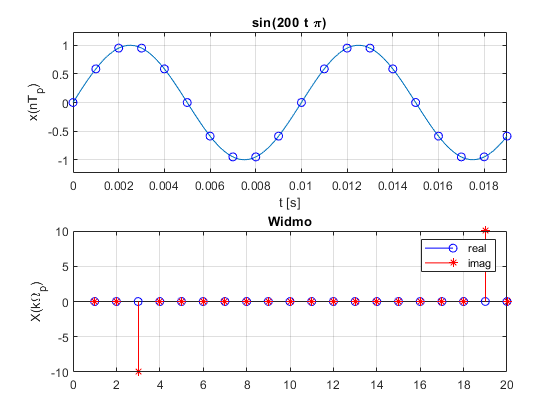


wk = fp*[0:N/2-1]/N;    % oś częstotliwości

figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(2,1,2)
stem(real(Xk),'ob'); grid on, hold on
stem(imag(Xk),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')
hold off

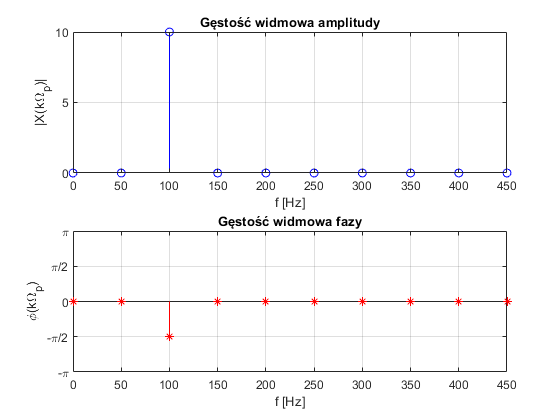


tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;

figure;
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
 
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'})
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');
hold off

### 1.6 Zadanie 6

Wyznacz widmo sygnału x3(t) = sin(2πf3t) dla N = 10 próbek gdzie f3 = 150[Hz]. Zjawisko widoczne na wykresach to tzw. przeciek widma.

clear all;
close all

syms t w

N = 10; % liczba próbek
fp = 1000; % Hz
Tp = 1/fp;
A0 = 5;
A1 = 1; f3 = 150; % Hz
x1 = A1*sin(2*pi*f3*t);
x = x1;

tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);

for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k + 1) + xn(n + 1)*(exp(-1j*2*pi/N)^(k*n));
    end
end

Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 2.3639e-14

disp('DFT error:'); disp(dft_err);

DFT error:
   2.3639e-14



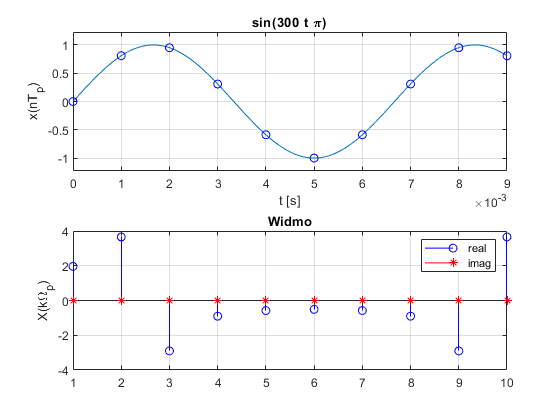


wk = fp*[0:floor(N/2)-1]/N;

figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(2,1,2)
stem(real(Xk),'ob'); grid on, hold on
stem(imag(Xk),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')
hold off

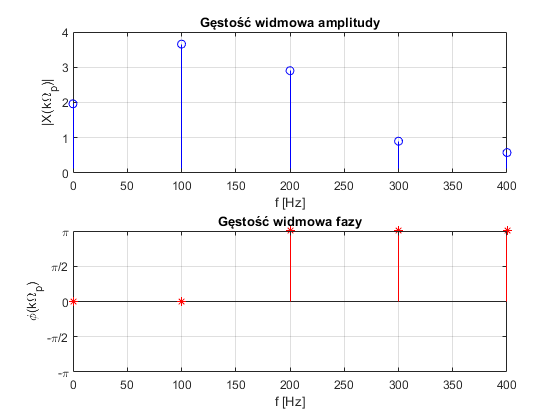


tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;

figure;
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
 
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'})
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');
hold off

### 1.7 Zadanie 7

Wyznacz widmo sygnału x3(t) = sin(2πf3t) dla N = 10 próbek gdzie f3 = 150[Hz] i zapoznaj się z nim. Spostrzeżenia zapisz w sprawozdaniu. Zjawisko widoczne na wykresach to tzw. przeciek widma.

### a) okno trójkątne

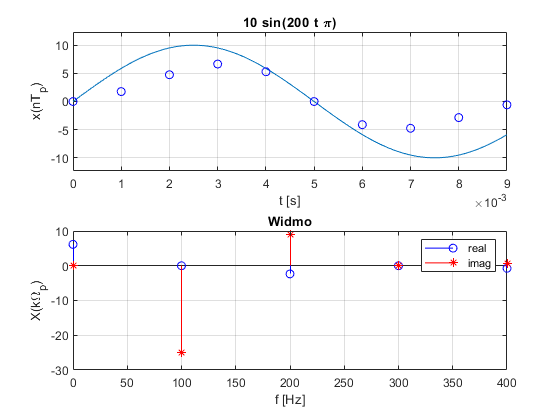

clear;
close all;
syms t w

N = 10;
fp = 1000; % Hz
Tp = 1/fp;
A1 = 10; f1 = 100; % Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

tn = [0:N-1]*Tp;
wk = fp*[0:N/2-1]/N;
xn = double(subs(x,t,tn));
Xk = zeros(1,N);

xn = xn.*triang(N)';

for k = 0:N-1
    for n = 0:N-1
         Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
    end
end

figure(1);
subplot(2,1,1);
ezplot(x,[tn(1),tn(N)]); hold on; grid on;
plot(tn, xn, 'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(2,1,2);
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');
title('Widmo');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]');
legend('real', 'imag');

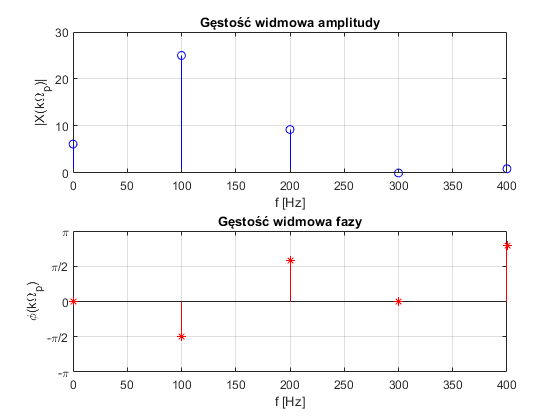


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;

figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');

subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'})
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

### b) okno Gaussa

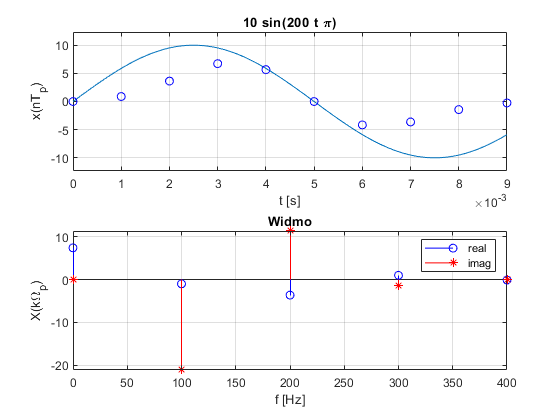

clear;
close all;
syms t w

N = 10;
fp = 1000; % Hz
Tp = 1/fp;
A1 = 10; f1 = 100; % Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

tn = [0:N-1]*Tp;
wk = fp*[0:N/2-1]/N;
xn = double(subs(x,t,tn));
Xk = zeros(1,N);

xn = xn.*window(@gausswin,N,2.5)';

for k = 0:N-1
    for n = 0:N-1
         Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
    end
end

figure(1);
subplot(2,1,1);
ezplot(x,[tn(1),tn(N)]); hold on; grid on;
plot(tn, xn, 'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(2,1,2);
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');
title('Widmo');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]');
legend('real', 'imag');

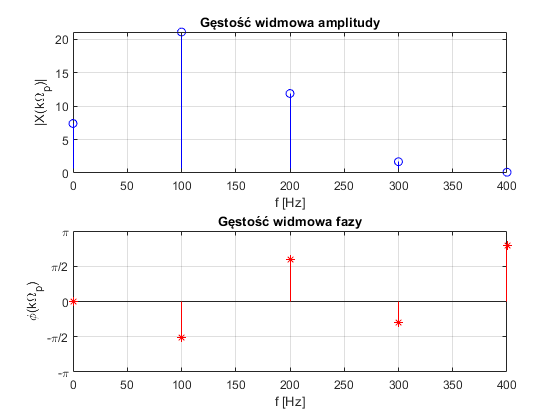


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;

figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');

subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'})
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

### c) Okno Czebyszewa

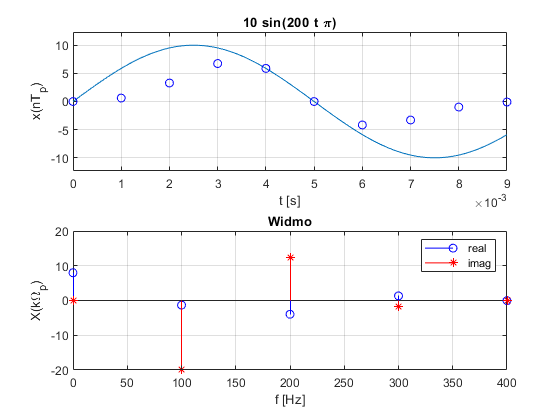

clear;
close all;
syms t w

N = 10;
fp = 1000; % Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; % Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

tn = [0:N-1]*Tp;
wk = fp*[0:N/2-1]/N;
xn = double(subs(x,t,tn));
Xk = zeros(1,N);

xn = xn.*chebwin(N)';

for k = 0:N-1
    for n = 0:N-1
         Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
    end
end

figure(1);
subplot(2,1,1);
ezplot(x,[tn(1),tn(N)]); hold on; grid on;
plot(tn, xn, 'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(2,1,2);
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');
title('Widmo');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]');
legend('real', 'imag');

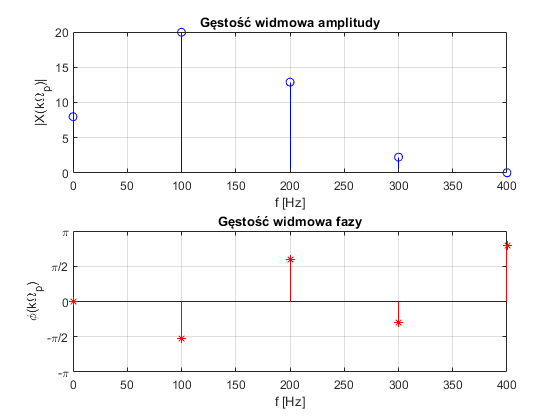


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;

figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');

subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'})
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

### Zadanie 1.8

Zdefiniuj sygnał `x = A1*sin(2*pi*f1*t) + A2*sin(2*pi*f2*t);` i sporządź wykresy dla `A2 = 5.0;` oraz `f2 = 200`. Spróbkowany sygnał `xn` przesuń cylicznie w prawo o 2 próbki w prawo, zaobserwuj zmiany w widmie i opisz je w sprawozdaniu.

clear;
close all;
syms t w

N = 10;
fp = 1000; % Hz
Tp = 1/fp;
A1 = 10; f1 = 100; % Hz
A2 = 5.0; f2 = 200;
x8 = A1*sin(2*pi*f1*t) + A2*sin(2*pi*f2*t);
x = x8;

tn = [0:N-1]*Tp;
wk = fp*[0:N/2-1]/N;
xn = double(subs(x,t,tn));
Xk = zeros(1,N);

Xk_fft = fft(xn,N);
dft_err = sum(abs(Xk_fft - Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   150



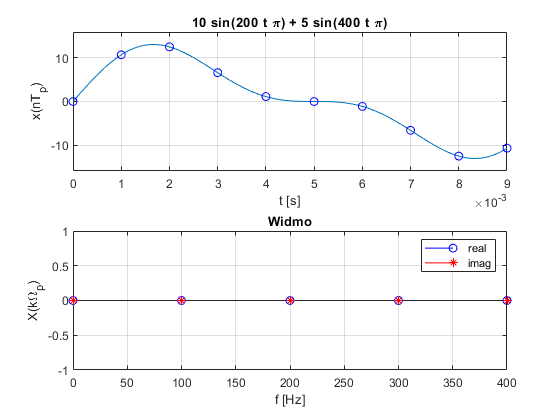


figure(1);
subplot(2,1,1);
ezplot(x,[tn(1),tn(N)]); hold on; grid on;
plot(tn, xn, 'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(2,1,2);
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');
title('Widmo');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]');
legend('real', 'imag');

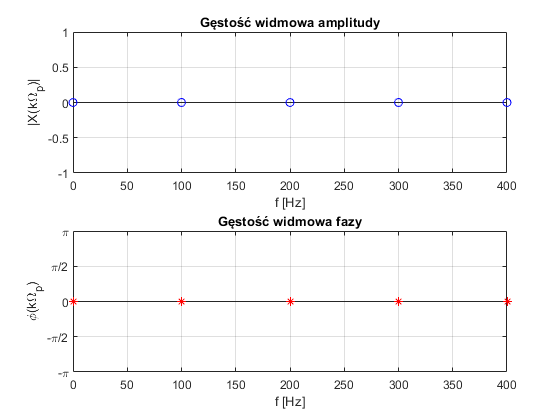


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;

figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');

subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'})
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

### 1.8 Przesunięcie cykliczne

clear;
close all;
syms t w

N = 10;
fp = 1000; % Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; % Hz
A2 = 5.0; f2 = 200

f2 = 200

x8 = A1*sin(2*pi*f1*t) + A2*sin(2*pi*f2*t);
x = x8;

tn = [0:N-1]*Tp;
wk = fp*[0:N/2-1]/N;
xn = double(subs(x,t,tn));
Xk = zeros(1,N);

%przesuniecie cykliczne
xm = zeros(1,N);
m = 2;
for n = 0:N-1
     xm(n+1) = xn(mod(n + m, N)+1);
end
xn = xm;

for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = Xk(k + 1) + xn(n + 1)*(exp(-1j*2*pi/N)^(k*n));
    end
end

Xk_fft = fft(xn,N);
dft_err = sum(abs(Xk_fft - Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   3.2165e-13



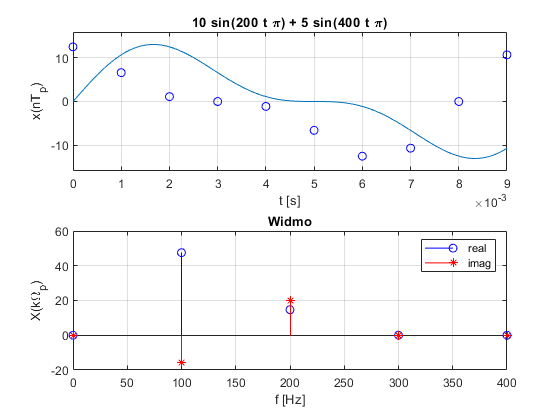


figure(1);
subplot(2,1,1);
ezplot(x,[tn(1),tn(N)]); hold on; grid on;
plot(tn, xn, 'ob');
xlabel('t [s]'); ylabel('x(nT_p)');

subplot(2,1,2);
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');
title('Widmo');
ylabel('X(k\Omega_p)'); xlabel('f [Hz]');
legend('real', 'imag');

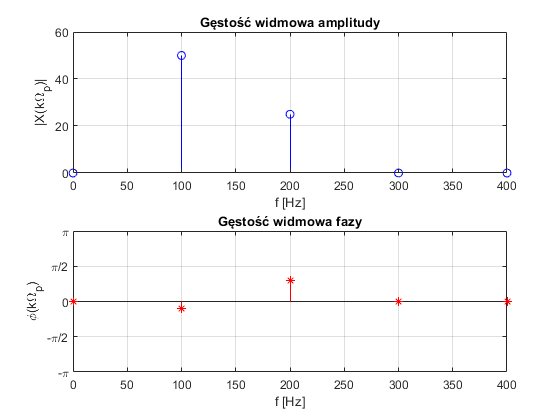


tol = 1e-2;
Xk(abs(Xk) < tol) = 0;

figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');

subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'})
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

### 1.9 Zadanie domowe

Zastąp iteracyjną implementajcę dyskretnej transformacji Fourieria macierzową realizacją. Wówczas nie będą potrzbne pętle `for ...end` a wystarczy mnożenie macierzowe aby uzyskać zespolone dyskretne widmo.

% Funkcja w matlabie

W = dftmtx(N);
Xk = xn*W;


% Funkcja tworzona

W = zeros(N,N);
omega = exp(-1j*2*pi/N);
for u = 0:N-1
    for v = 0:u
        W(u+1,v+1) = omega.^(u*v);
    end
end

% sklejenie macierzy, pozbycie się "podwójnej przekątnej"
W = W.'+W-W.*eye(N); % macierz transponowana bez sprzężenia

Xk = xn*W;